# Newton fractal 

#### Introduzione

Un numero complesso è un numero della forma $x + iy$, dove $(x, y) \in R^2$.

Spesso i numeri complessi vengono rappresentati nel piano di Gauss, possiamo immagine questo piano come uno spazio vettoriale di dimensione 2 la cui base è  $B= \{ (1, 0), (0, i) \}$.

% Variabili globali
global x y X Y tol Kmax;
x = linspace(-2, 2, 1000);
y = linspace(-2, 2, 1000);
[X, Y] = meshgrid(x, y);
tol = 0.0005;
Kmax = 30;


#### Idea alla base

L'idea che sta alla base dei frattali di Newton è proprio il metodo di Newton per la ricerca delle radici di una funzione non lineare (per semplicità considereremo solo funzioni che sono polinomi ). 

A questo punto ci chiediamo, **che effetti ha la scelta del punto **$x_0$** nel metodo di Newton**? 

Quindi, consideriamo il piano di Gauss, ed immaginiamo di applicare il metodo di Newton ad ogni punto di una certa sezione del piano. Dopo un certo numero di iterazioni (a meno di problemi dovuti al metodo) ogni punto sarà arrivato intorno ad una radice. Adesso immaginiamo di colorare tutti questi punti, e di riavvolgere le operazioni che abbiamo eseguito, in modo da avere ogni punto nella sua posizione iniziale, ma del colore della radice che ha trovato. 

Quello che uno si aspetterebbe è una divisione più o meno netta di colori, ma invece quello che troviamo è un frattale.

Vediamo un esempio con $p(z) = z^3 - 1$

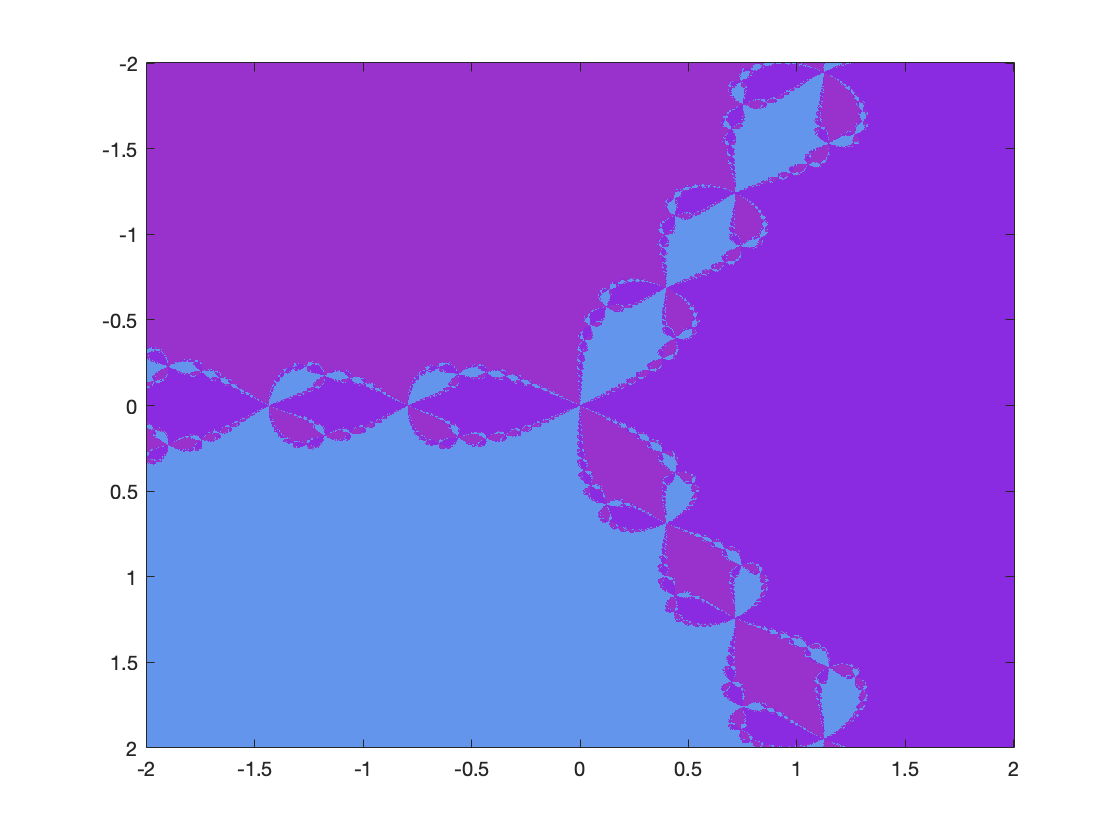

deg = 3;
f = @(z) z.^3 - 1;
df = @(z) 3*z.^2;
root = [1; -1/2 + 1i*sqrt(3)/2; -1/2 - 1i*sqrt(3)/2];

Z = X + 1i*Y;

for i=1 : Kmax
   Z = Z - f(Z) ./ df(Z);
end

Zf = zeros(length(X), length(Y));
for i=1 : deg
    Zf(:, :) = Zf + (abs(Z - root(i)) < tol)*i;
end

figure;
map = [138 43 226; 100 149 237; 153 50 204];
map = map ./ 255;
colormap(map);
image(x, y, Zf);

#### Cosa rappresenta un frattale di Newton

Quindi un frattale di Newton rappresenta, fissato un polinomio, la radice che troveremmo applicando Newton in tutti i punti del segmento che stiamo analizzando. 

Ciò significa che esistono regioni del piano complesso dove anche **infinitesime** variazioni nella scelta di $x_0$ potrebbero cambiare completamente la radice trovata. 

 
Kmax = 100;
tol = 0.001;
f = @(x) x.^3 - 8;
df = @(x) 3*x.^2;

% Piccole variazioni nell'input cambiano la radice trovata
%x0 = -1i*1.38 + 0.79;  %-1.0000 - 1.7321i
%x0 = -1i*1.38 + 0.8    %-1.0000 + 1.7321i
%x0 = -1i*1.38 + 0.81;  %2

i = 1; e = 1;
x = x0 - f(x0)/df(x0);

while i < Kmax && e > tol
    px = x;
    x = px - f(x)/df(x);
    e = abs((x - px)/x);
    i = i+1;
end

i

i = 7

alpha = x

alpha = 2.0000

Possiamo inoltre notare che le regioni "vicine" ad una certa radice avranno sempre lo stesso colore, ed appunto il "caos" si trova ai confini tra queste regioni. Possiamo anche osservare che preso un certo intorno di un punto $x$ i punti che si trovano in questo intorno tendono tutti a convergere verso la stessa radice, o ci sono infiniti punti che convergono verso ogni radice. 

Un altra domanda che ci si può porre è: "I casi particolari in cui il metodo di Newton fallisce a trovare una radice, possono essere visualizzati?". La risposta è si. Consideriamo il polinomio $p(z) = z^3 - 2z +2$, la sua derivata è ovviamente $p'(z) = 3z^2 - 2$. Proviamo a considerare due iterazioni del metodo di Newton con $x_0 = 0$:


$$x_1 = 0 - \frac 2 2 = 1 \\
x_2 = 1 - \frac{1 -2 + 2}{3 - 1} = 0 \\
...$$


Quindi ci troveremo in un ciclo infinito. Questo graficamente può essere visto dai punti in cui il frattale è nero. Quindi abbiamo anche uno strumento per verificare quali sono degli intorni in cui il metodo di Newton da problemi ad occhio. Inoltre è possibile anche diminuire il numero di iterazioni per vedere graficamente quanti punti convergono per ogni iterazione.

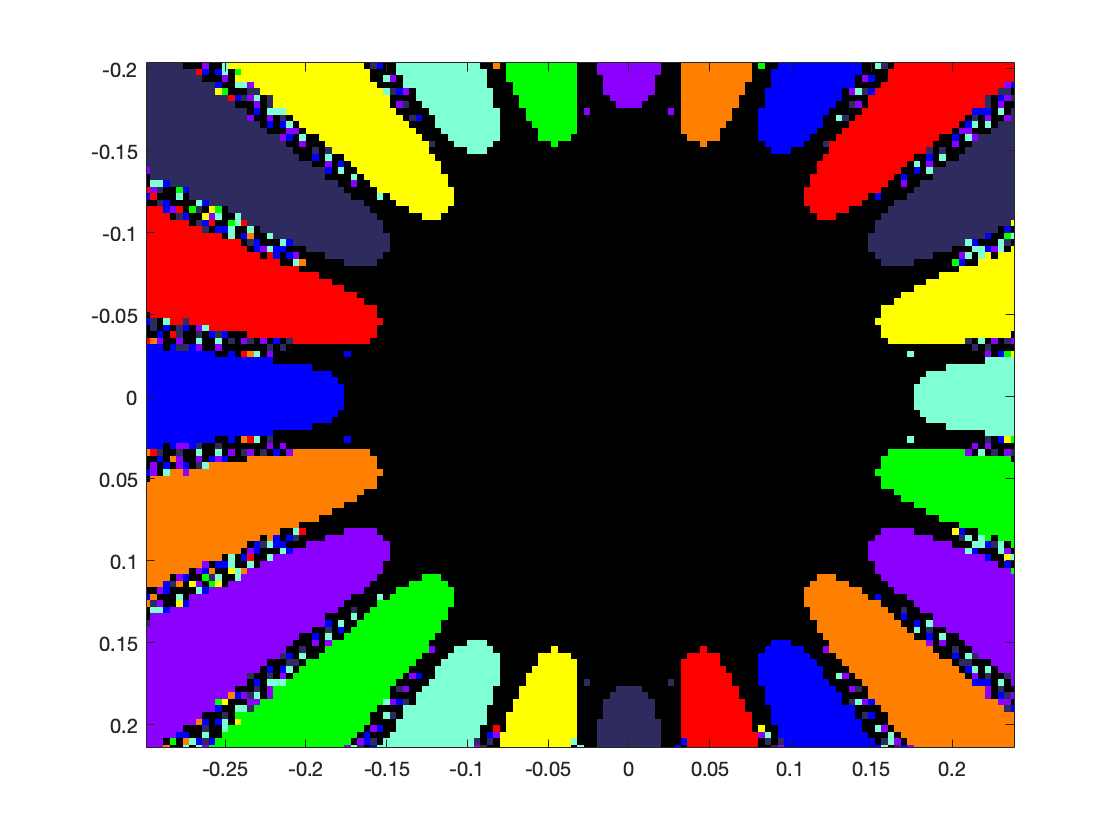

clear roots;
deg = 8;
p = [1 0 0 0 15 0 0 0 -16];
f = @(x) x.^8 + 15*x.^4 - 16;
df = @(x) 8*x.^7 + 60*x.^3;
root = roots(p);

Z = X + 1i*Y;

for i=1 : Kmax
   Z = Z - f(Z) ./ df(Z);
end

Zf = zeros(length(X), length(Y));
for i=1 : deg
    Zf(:, :) = Zf + (abs(Z - root(i)) < tol)*i;
end

for i=1 : length(X)
    for j=1 : length(Y)
       if Zf(i, j) == 0
          Zf(i, j) = deg + 1;
       end
    end
end

figure;
map = [255, 0, 0; 255, 127, 0; 255, 255, 0; 0, 255, 0; 0, 0, 255; 46, 43, 95; 139, 0, 255; 127, 255, 212; 0 0 0];
map = map ./ 255;
colormap(map);
image(x, y, Zf);